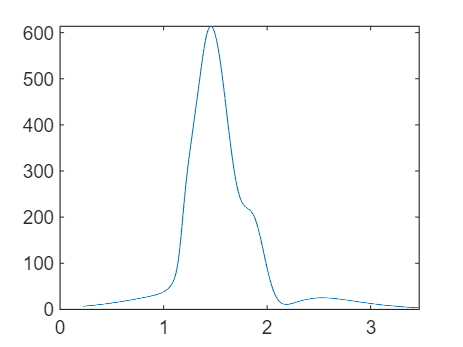

clear;close all;
nPoint = 2^18;
z0 = 10;
T=17.5;
sigma = (3.25/1024)*70:(3.25/1024):(nPoint+69)*(3.25/1024);
zerodata = zeros(1,261120);
% sigma = [sigma zerodata];
fSigma = fitfSigma(sigma);
refractiveIndex=fitfPigma("N_BK",sigma);
% pSigma=(refractiveIndex);
pSigma=-4*pi*z0.*sigma+4*pi.*(refractiveIndex-1)*T.*sigma;
fSigma=[fSigma(1:2^10) zerodata];
pSigma=[pSigma(1:2^10) zerodata];
iSigma = fSigma.*exp(1i*pSigma);
plot(sigma,fSigma);
xlim([0 2^10*(3.25/1024)+(3.25/1024)*69]);

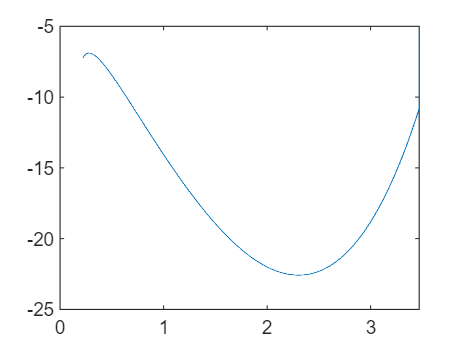

plot(sigma,pSigma);
xlim([0 2^10*(3.25/1024)+(3.25/1024)*69]);


coefficient1=polyfit(sigma(1:2^10),pSigma(1:2^10),1)

coefficient1 =    -3.1032  -11.2481


wrapToPi(coefficient1(2))

ans = 1.3183

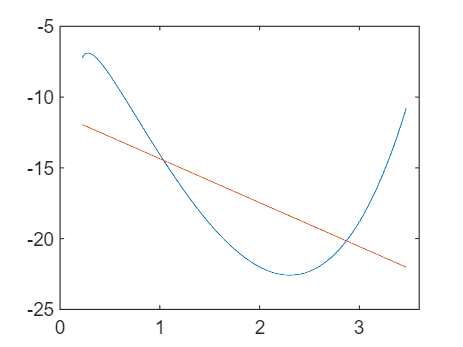

plot(sigma(1:2^10),pSigma(1:2^10));
LSM=polyval(coefficient1,sigma(1:2^10));
hold on
plot(sigma(1:2^10),LSM);
xlim([0 3.6])
hold off

deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase = (angle(ifftIsigma));
%找到振幅最大值
[max1,index]= max(intensity)

max1 = 0.3672

index = 1129

zData(index)

ans = 0.6785

phase(index)

ans = -1.5586

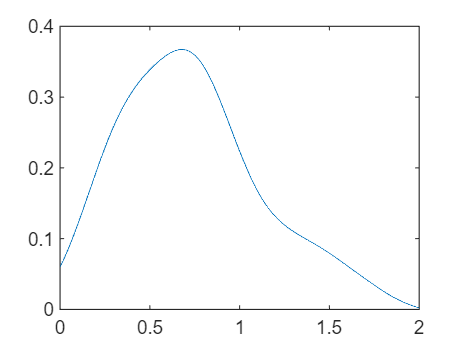

plot(zData,intensity);
xlim([0 2]);

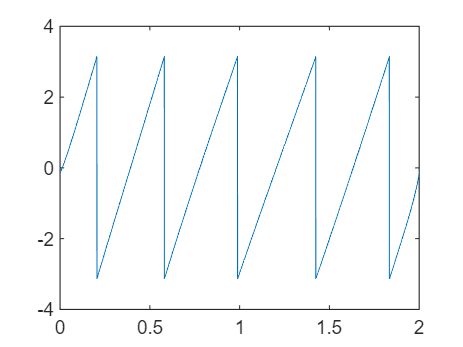

plot(zData,phase);
xlim([0 2]);

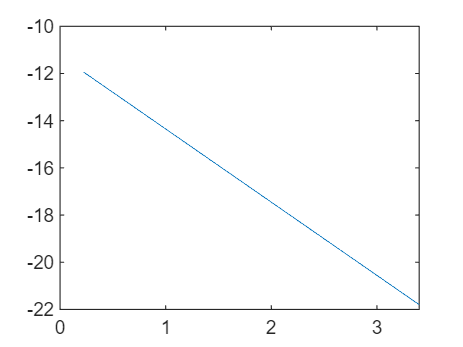


% %unwrap phase,from z=9 to z=11.
% % unwrapZ1 = zData(abs(zData-15)<0.001);
% unwrapZend = zData(abs(zData-2)<0.001);
% unwrapZ_1 = zData(abs(zData-0.3)<0.001);
% %first phase phi0=4*pi*1.45*(unwrap(1)-10)
% unwrapN1 = index;
% unwrapNe = find(zData==unwrapZend(end));
% unwrapN_1 = find(zData==unwrapZ_1(1));
% unwrapPha = zeros(1,length(zData));
% 
% unwrapPha(unwrapN1) = phase(index);
% for n = unwrapN1+1:unwrapNe
%     diff = phase(n)-phase(n-1);
%     if diff > pi/2
%        unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
%     elseif diff < -pi/2
%        unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
%     else
%        unwrapPha(n) = unwrapPha(n-1)+diff;
%     end
% end
% 
% for n = unwrapN1:-1:unwrapN_1
%     diff = phase(n)-phase(n-1);
%     if diff > pi/2
%        unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
%     elseif diff < -pi/2
%        unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
%     else
%        unwrapPha(n-1) = unwrapPha(n)-diff;
%     end
% end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

% nPoint = 2^18;
% z0 = 10;
% sigma = 0:0.0038:(nPoint-1)*0.0038;
% zerodata = zeros(1,261120);
% sigma = [sigma zerodata];
% fSigma = fitfSigma(sigma);
% pSigma=-4*pi*((35+z0)-10*sigma).*sigma;
% coefficient=polyfit(sigma(1:2^10),pSigma(1:2^10),1); 
% LSM=polyval(coefficient,sigma(1:2^10));
% pSigma=coefficient(1)*sigma+coefficient(2);
fSigma=[fSigma(1:2^10) zerodata];
pSigma=[LSM zerodata];
iSigma = fSigma.*exp(1i*pSigma);
plot(sigma,pSigma);
xlim([0 3.4]);

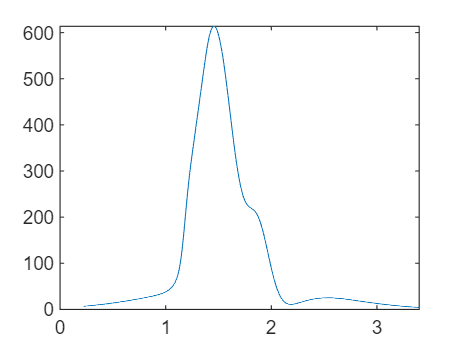

plot(sigma,fSigma);
xlim([0 3.4]);

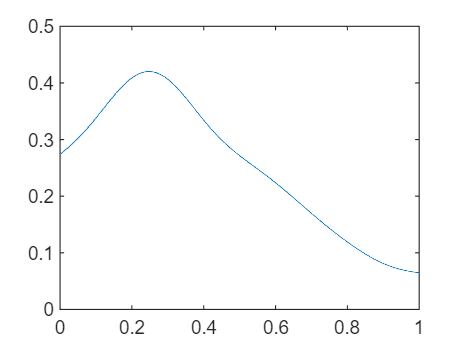


deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity1 = abs(ifftIsigma);
phase = (angle(ifftIsigma));
plot(zData,intensity1);
xlim([0 1])

plot(zData,phase);
xlim([0 1])

%找到振幅最大值
[max11,index1]= max(intensity1)

max11 = 0.4201

index1 = 412

za1 = zData(index1)

za1 = 0.2476

phase(index1)

ans = 0.6297

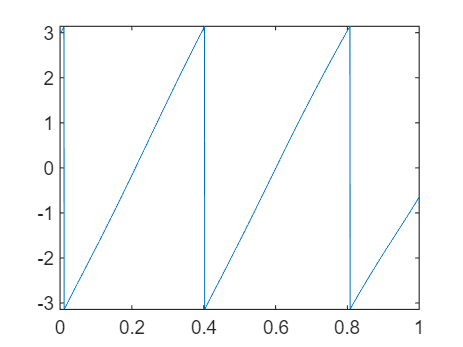

hold on
plot([6.1266,6.1266],[-pi,phase(index1)]);
plot([6.2325,6.2325],[-pi,0.0017]);
hold off
ylim([-pi pi]);

%unwrap phase,from z=9 to z=11.
% unwrapZ1 = zData(abs(zData-15)<0.001);
% unwrapZend = zData(abs(zData-2)<0.001);
% unwrapZ_1 = zData(abs(zData-0.1)<0.001);
% %first phase phi0=4*pi*1.45*(unwrap(1)-10)
% unwrapN1 = index1;
% unwrapNe = find(zData==unwrapZend(end));
% unwrapN_1 = find(zData==unwrapZ_1(1));
% unwrapPha = zeros(1,length(zData));
% 
% unwrapPha(unwrapN1) = phase(index1);
% for n = unwrapN1+1:unwrapNe
%     diff = phase(n)-phase(n-1);
%     if diff > pi/2
%        unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
%     elseif diff < -pi/2
%        unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
%     else
%        unwrapPha(n) = unwrapPha(n-1)+diff;
%     end
% end
% 
% for n = unwrapN1:-1:unwrapN_1
%     diff = phase(n)-phase(n-1);
%     if diff > pi/2
%        unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
%     elseif diff < -pi/2
%        unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
%     else
%        unwrapPha(n-1) = unwrapPha(n)-diff;
%     end
% end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
% % xlim([15 17])
% coefficient=polyfit(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe),1); 
% LSM1=polyval(coefficient,zData(unwrapN_1:unwrapNe));
% hold on 
% plot(zData(unwrapN_1:unwrapNe),LSM1);
% phase1=unwrapPha(unwrapN_1:unwrapNe);
% zData1=zData(unwrapN_1:unwrapNe);
% zerophase=phase1(abs(phase1-0)<0.005)
% zData1(phase1==zerophase)
% hold off
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe)-LSM1);

a1=coefficient1(1)+4*pi*z0

a1 = 122.5605

a0=wrapToPi(coefficient1(2))

a0 = 1.3183

za=z0-(a1/(4*pi))

za = 0.2469

zp=z0-((a1+a0*0.6453)/(4*pi))

zp = 0.1792


unwrapZend = zData(abs(zData-1)<0.001);
unwrapZ_1 = zData(abs(zData-0.1)<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = index1;
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));

unwrapPha(unwrapN1) = phase(index1);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end

for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
% xlim([15 17])
% coefficient=polyfit(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe),1); 
% LSM1=polyval(coefficient,zData(unwrapN_1:unwrapNe));
% hold on 
% plot(zData(unwrapN_1:unwrapNe),LSM1);
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
zerophase=phase1(abs(phase1-0)<0.001)

zerophase = -5.6428e-04

zp1 = zData1(phase1==zerophase)

zp1 = 0.2097


zp1-zp

ans = 0.0305

za1-za

ans = 6.5180e-04

function fSigma = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
end

function index = fitfPigma(x,sigma)
lamda = 1./sigma;
if x=="N_BK"
    index2 = (1.03961212*lamda.^2)./(lamda.^2-0.00600069867)+(1.01046945*lamda.^2)./(lamda.^2-103.560653)+...
        (0.231792344*lamda.^2)./(lamda.^2-0.0200179144)+1; 
    index = sqrt(abs(index2));
elseif x=="N_F2"
    index2 = (1.39757037*lamda.^2)./(lamda.^2-0.00995906143)+(0.159201403*lamda.^2)./(lamda.^2-0.0546931752)+...
        (1.268654300*lamda.^2)./(lamda.^2-119.2483460)+1; 
    index = sqrt(abs(index2));
elseif x=="N_SF11"
    index2 = (1.73759695*lamda.^2)./(lamda.^2-0.013188707)+(0.313747346*lamda.^2)./(lamda.^2-0.0623068142)+...
        (1.89878101*lamda.^2)./(lamda.^2-155.23629)+1; 
    index = sqrt(abs(index2));
elseif x=="LbS"
    index2 = (1.5039759*lamda.^2)./(lamda.^2-0.0740288^2)+(0.55069141*lamda.^2)./(lamda.^2-0.1216529^2)+...
        (6.5927379*lamda.^2)./(lamda.^2-20.072248^2)+1; 
    index = sqrt(abs(index2));
elseif x=="JHS" 
    index2 = 2.9713+(5.1891*10^(-5))./(1.2280*10^(-5)-lamda.^(-2))-4.2950*10^(-8).*lamda.^2;
    index = sqrt(abs(index2));
else 
    error("其他");
end
end
